% Create the input as white noise with a strong sinusoidal component
f = 0.1*randn(1,10000);
y = zeros(1,length(f));
e = zeros(1,length(f));
M=25;  delta = .001; lambda = .95;
x = RLSFilter('initial',lambda, M, delta);
L = length(f);
Delta=1;
f_delay = zeros(1,Delta+1);
for J = 1:L
    f(J) = f(J) + 3*sin(2*pi*J/12);
    for K = Delta+1:-1:2
        f_delay(K) = f_delay(K-1);
    end
    f_delay(1) = f(J);
    [y(J),b] = RLSFilter(f_delay(Delta+1),f(J));
    e(J) = f(J) - y(J);
%     Delta = Delta + 1;
end

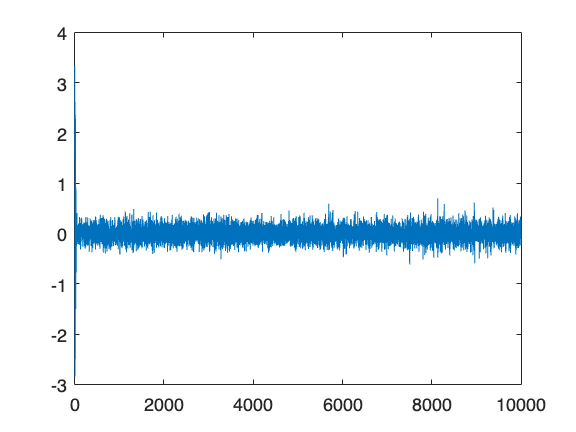

plot(e)

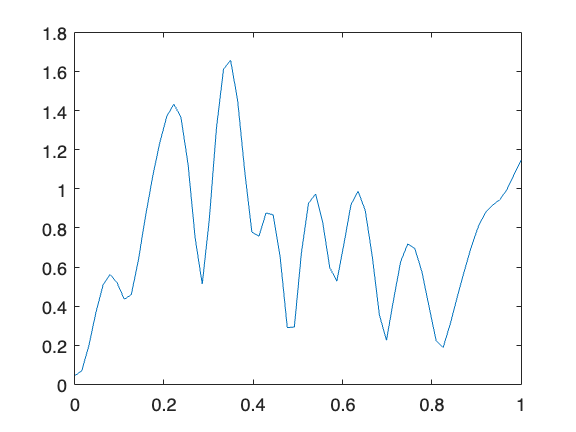

H1 = abs(freqz(b,1,64));
wf = linspace(0,1,64);

plot(wf,H1)